# `antbounds` documentation

The `antbounds` function plots line data from the line data in the MEaSURES Antarctic Boundaries for IPY 2007-2009 from Satellite Radar dataset Version 2. 

The Antarctic Boundaries dataset is described on the NSIDC site [here](http://nsidc.org/data/NSIDC-0709). An overview of the tools in this AMT plugin can be found [here](Antbounds_Contents.html).

## Syntax

## Description

`antbounds(datatype)` plots any of the following datatypes: 

- `'coast'` seaward limit of the ice sheet

- `'gl'` landward limit of flexure detected by InSAR

- `'shelves'` a cell array of all ice 180 ice shelves in the dataset

- `'shelfname'` any of the shelf names in the dataset, must be exactly one of the following: 

`antbounds(datatype,PropertyName,PropertyValue,...)` formats the line properties with linewidth, color, etc. 

`antbounds(...,'polyshape')` plots the grounding line, coast line, or ice shelves as polyshape objects rather than as line objects. This option requires Matlab version R2017b or newer. Polyshape properties are equivalent to patch or fill properties (e.g., FaceColor, EdgeColor, FaceAlpha, etc.)

`antbounds(...,'km')` plots in polar stereographic kilometers rather than meters. 

`h = antbounds(...)` returns a handle `h` of the plotted object(s) 

## Line Examples

Plot a coastline like this: 

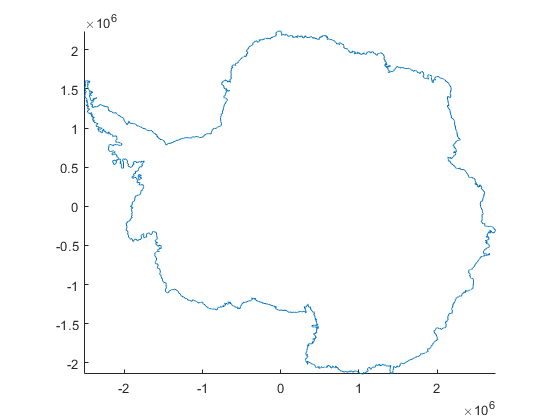

antbounds('coast')

Overlay a red grounding line like this: 

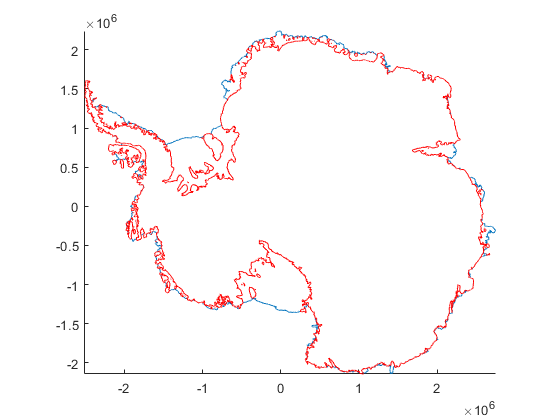

antbounds('gl','color','r')

Outline Amery Ice Shelf with a fat magenta line like this: 

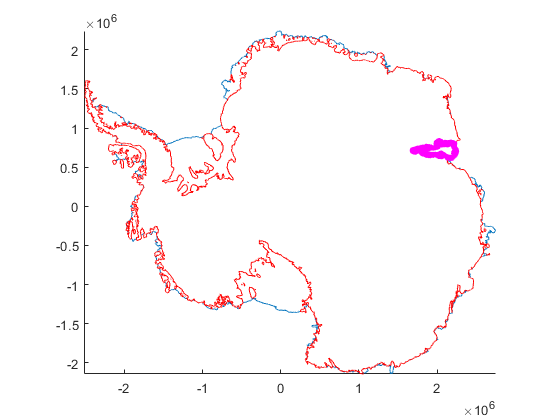

antbounds('amery','m','linewidth',4)

## Polyshape Examples

If you have Matlab R2017b or newer, you can fill in the outlines of the grounding line, coast line, or ice shelves using the `'polyshape'` feature. The default polyshape formatting is typically a semitransparent blue: 

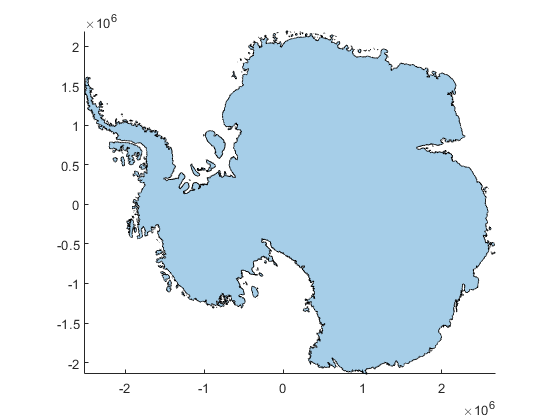

figure
antbounds('gl','polyshape')

If you'd like to plot opaque red ice shelves with thick green outlines, try this: 

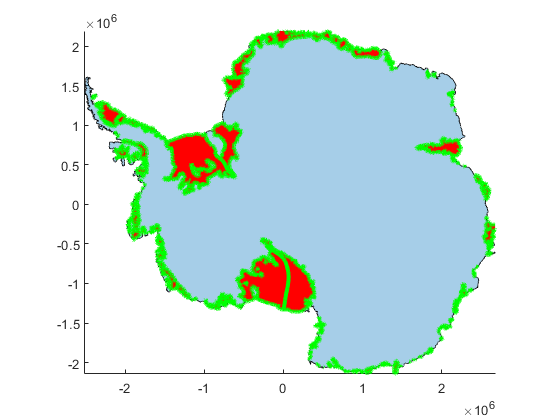

antbounds('shelves','polyshape',...
   'facecolor','r',...
   'facealpha',1,...
   'linewidth',3,...
   'edgecolor','g')

## Citing this dataset

If you use this dataset, please cite the following: 

- **The dataset:** Mouginot, J., B. Scheuchl, and E. Rignot. 2017. MEaSUREs Antarctic Boundaries for IPY 2007-2009 from Satellite Radar, Version 2. [Indicate subset used]. Boulder, Colorado USA. NASA National Snow and Ice Data Center Distributed Active Archive Center. [http://dx.doi.org/10.5067/AXE4121732AD](http://dx.doi.org/10.5067/AXE4121732AD). 

- **Literature citation:** Rignot, E., S. S. Jacobs, J. Mouginot, and B. Scheuchl. 2013. Ice-shelf melting around Antarctica, Science. 341. 266-270. [http://dx.doi.org/10.1126/science.1235798](http://dx.doi.org/10.1126/science.1235798). 

- **Antarctic Mapping Tools:** Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function and supporting documentation were written by [Chad A. Greene](http://www.chadagreene.com) of the University of Texas Institute for Geophysics (UTIG), November 2016. Updated May 2017 and May 2018. 